# 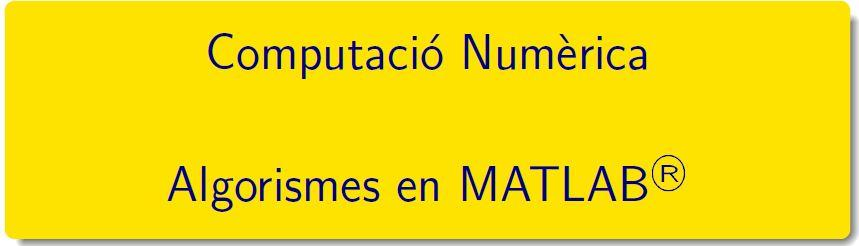

===========================================================================

# Pràctica  - Càlcul de sèries

## Enunciat

Leibniz va obtenir la següent sèrie matemàtica (1682):    $\displaystyle\sum_{n=0}^{\infty} \frac{(-1)^n}{2n+1} = 1 - \frac{1}{3} + \frac{1}{5} - \dots = \frac{\pi}{4}$

#### Exercici 1

- Determineu quants termes cal sumar per obtenir la suma amb un error més petit que $10^{-4}$.

- **Sèries alternades convergents: ** Si $\displaystyle\sum_{n=1}^{\infty}(-1)^{n+1}a_n\,,$ per $a_n>0$ i $\{a_n\}$successió monòtona decreixent que tendeix a zero, llavors la sèrie és convergent i el reste $R_N=S-S_N$  es pot fitat per $|R_n|\leq |a_{n+1}|$. 

syms k f(k)
assume(k,'positive')
f(k) = (-1)^k/(2*k+1);
N = solve(abs(f(k))==0.0001,k)

$$N = \frac{9999}{2}$$

var = vpa(N)

$$var = 4999.5$$

#### Exercici 2

- Posseu a prova la vostra predicció, escriviu codi de Matlab® per a calcular el valor de la suma amb un error més petit que $10^{-4}$. 

format shortG
result = [1];
it = 1;
diff = inf

diff =    Inf


aprox = [inf];
n = 100000;
while diff > 0.0001 && it < n
    rold = result;
    result(it + 1) = result(it) + ((-1)^it)/(2*it+1);
    it = it + 1;
    diff = abs(result(it)-result(it-1));
    aprox(it) = abs(result(it)-result(it-1));
end
result(it), it

ans =       0.78545


it =         5001


#### Exercici 3

- Presenteu els resultats que s'obtenen en una taula, aquesta taula ha de mostrar $N,\ S_N,\ |S_N-\frac\pi4|$ i l'error aproximat $|S_{N+1}-S_N|$. Comenteu els resultats que s'obtenen. 

R  = [1:it; result;abs(result-(pi/4));aprox]';
TR = array2table(R,"VariableNames",{'N','S(N)','S(N)-PI/4','Error Aproximat'}); disp(TR)

     N       S(N)      S(N)-PI/4     Error Aproximat
    ____    _______    __________    _______________

       1          1        0.2146             Inf   
       2    0.66667       0.11873         0.33333   
       3    0.86667      0.081269             0.2   
       4    0.72381      0.061589         0.14286   
       5    0.83492      0.049522         0.11111   
       6    0.74401      0.041387        0.090909   
       7    0.82093      0.035536        0.076923   
       8    0.75427       0.03113        0.066667   
       9    0.81309      0.027693        0.058824   
      10    0.76046      0.024938        0.052632   
      11    0.80808      0.022681        0.047619   
      12     0.7646      0.020797        0.043478   
      13     0.8046      0.019203            0.04   
      14    0.76756      0.017835        0.037037   
      15    0.8

#### Exercici 4

- Pel tamany de la taula, és complicat poder fer una anàlisi de l'error, representeu gràficament l'error real $|S_N-\frac\pi4|$ i l'error aproximat $|S_{N+1}-S_N|$.  Comenteu els resultats que s'obtenen. 

newR = result - (pi/4);
plot(1:it,abs(newR))
title('error absolut i aproximat'),axis([0,5000,0,0.01]),grid
legend('real','aproximat(el data1)')

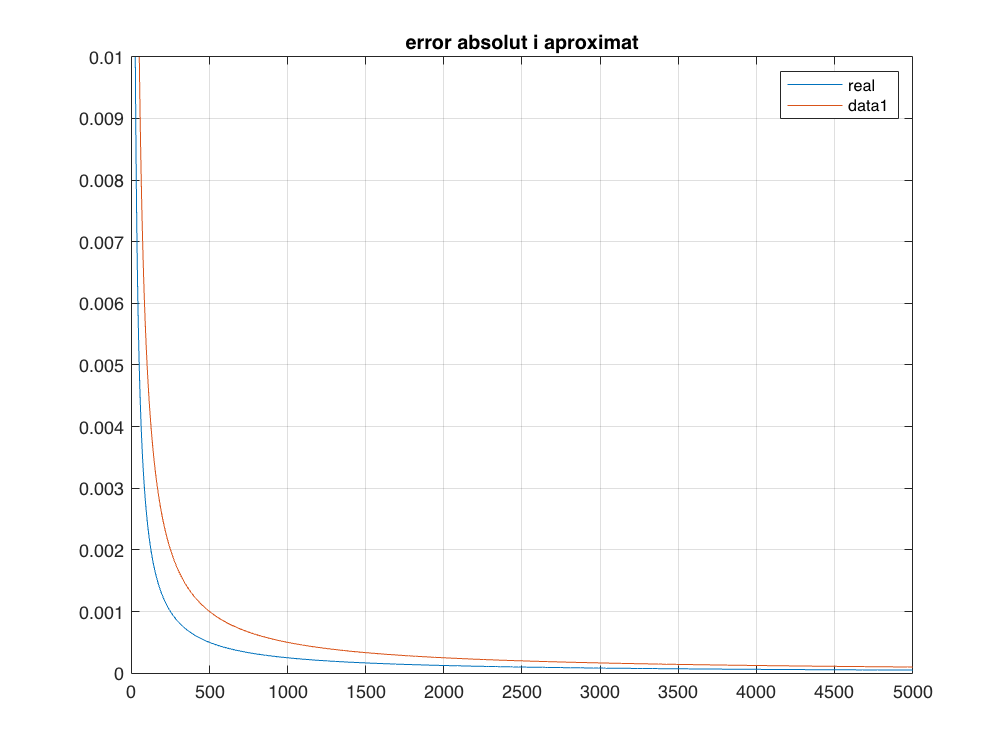

hold on
plot(1:it,aprox)
hold off

#### Exercici 5

- El nombre de termes que cal sumar, fent ús del criteri de sèries alternades és N=4999 però en realitat només caldrien N=2499. Com es reflexa aquest fet en els càlculs que heu realitzat? 

`Document preparat per M. Àngela Grau Gotés, 24 de febrer de 2022`